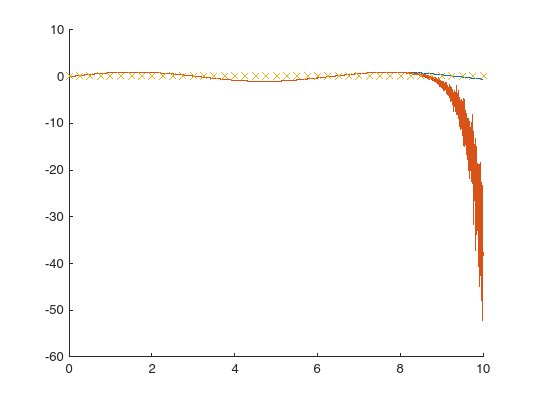

% clear variables
clear

% define region
startX = 0;
stepX = 0.25;
nPoints = 40;
endX = startX + stepX * nPoints;

X = startX:stepX:endX;

Y = sin(X);

% max deviation equidistant

%P = lagrange(X, Y);
P = newton(X, Y);
%P = polyfit(X, Y, length(X) - 1);

miniStepX = 0.001;
miniX = startX:miniStepX:endX;

F = sin(miniX);
P = polyval(P, miniX);

figure
hold on
plot(miniX, F)
plot(miniX, P)
plot(X, zeros(1, length(X)), "x")


fprintf("Max derivation: %.20f\n", maxDeviation(miniX, F, P))

Max derivation: 51.55820177893117772783


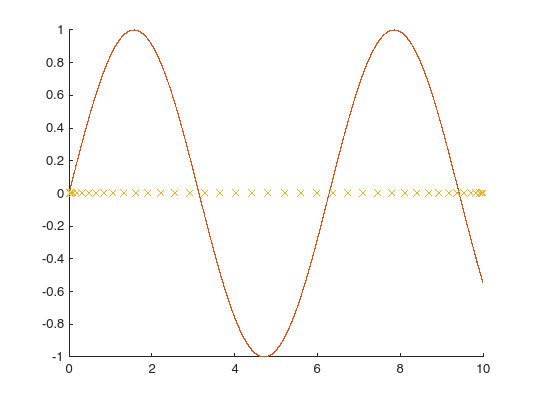



% max deviation Chebyshev

rT = chebyshevRoots(startX, endX, nPoints);

Y = sin(rT);

%P = lagrange(X, Y);
P = newton(rT, Y);
%P = polyfit(X, Y, length(X) - 1);

miniStepX = 0.001;
miniX = startX:miniStepX:endX;

F = sin(miniX);
P = polyval(P, miniX);

figure
hold on
plot(miniX, F)
plot(miniX, P)
plot(rT, zeros(1, length(rT)), "x")


fprintf("Max derivation: %.20f\n", maxDeviation(miniX, F, P))

Max derivation: 0.00328250867153584425
